clear all
cd /media/DataMOBsRAIDN/ProjectEmbReact/Figures/RiskAssessment
load('RiskAsess-FalsePosMat.mat')
load('RiskAsessMat.mat','Wavelet')
load('RiskAsessMat.mat','freqCoh','freqSpec')
BefTime=12;
tps=[0:0.01:BefTime*2/1e4];
Structures={'B','P','H'};
StructurePairs={'B_P','B_H','P_H'};
SessTypes={'TestPre','TestPost','UMazeCond','TestPre_EyeShock','TestPost_EyeShock','UMazeCond_EyeShock','UMazeCondBlockedShock_EyeShock','UMazeCondBlockedSafe_EyeShock'};


AllMov=[];
AllPos=[];
AllEKG=[];
for st=1:length(Structures)
    AllSpec.(Structures{st})=[];
    AllLFP.(Structures{st})=[];
end
for st=1:length(StructurePairs)
    AllCoh.(StructurePairs{st})=[];
end
for ss=1:length(SessTypes)
    for mm=1:length(RiskAsess.(SessTypes{ss}).ToShockMov)
        if not(isempty(RiskAsess.(SessTypes{ss}).ToShockMov{mm}))
            AllMov=[AllMov;RiskAsess.(SessTypes{ss}).ToShockMov{mm}];
            for st=1:length(Structures)
                AllSpec.(Structures{st})=cat(3,AllSpec.(Structures{st}),RiskAsess.(SessTypes{ss}).ToShockSpec.(Structures{st}){mm});
                AllLFP.(Structures{st})=[AllLFP.(Structures{st}),RiskAsess.(SessTypes{ss}).ToShockLFP.(Structures{st}){mm}];
            end
            for st=1:length(StructurePairs)
                AllCoh.(StructurePairs{st})=cat(3,AllCoh.(StructurePairs{st}),RiskAsess.(SessTypes{ss}).ToShockCoh.(StructurePairs{st}){mm});
            end
            AllEKG=[AllEKG;RiskAsess.(SessTypes{ss}).ToShockEKG{mm}];
            AllPos=[AllPos;RiskAsess.(SessTypes{ss}).ToShockPos{mm}];
        end
    end
end

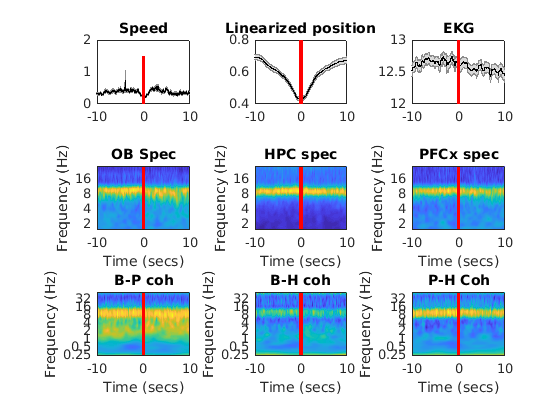


figure
subplot(3,3,1)
shadedErrorBar(tps-BefTime/1e4,nanmean(AllMov(:,:)),stdError(AllMov(:,:)));
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('Speed')
subplot(3,3,2)
shadedErrorBar(tps-BefTime/1e4,nanmean(AllPos(:,:)),stdError(AllPos(:,:)));
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('Linearized position')
subplot(3,3,3)
shadedErrorBar(tps(20:end-20)-BefTime/1e4,nanmean(AllEKG(:,20:end-20)),stdError(AllEKG(:,20:end-20)));
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('EKG')
subplot(3,3,4)
plotscalogramfreq_SB(Wavelet.OutParams.FourierFactor,Wavelet.OutParams.sigmaT,mean(AllSpec.B,3)',freqSpec,tps-BefTime/1e4,Wavelet.OutParams.normalizedfreq)
colorbar off
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('OB Spec')
subplot(3,3,5)
plotscalogramfreq_SB(Wavelet.OutParams.FourierFactor,Wavelet.OutParams.sigmaT,mean(AllSpec.H,3)',freqSpec,tps-BefTime/1e4,Wavelet.OutParams.normalizedfreq)
colorbar off
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('HPC spec')
subplot(3,3,6)
plotscalogramfreq_SB(Wavelet.OutParams.FourierFactor,Wavelet.OutParams.sigmaT,mean(AllSpec.P,3)',freqSpec,tps-BefTime/1e4,Wavelet.OutParams.normalizedfreq)
colorbar off
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('PFCx spec')
subplot(3,3,7)
plotscalogramfreq_SB(Wavelet.OutParams.FourierFactor,Wavelet.OutParams.sigmaT,mean(AllCoh.B_P,3)',freqCoh,tps-BefTime/1e4,Wavelet.OutParams.normalizedfreq)
colorbar off
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('B-P coh')
subplot(3,3,8)
plotscalogramfreq_SB(Wavelet.OutParams.FourierFactor,Wavelet.OutParams.sigmaT,mean(AllCoh.B_H,3)',freqCoh,tps-BefTime/1e4,Wavelet.OutParams.normalizedfreq)
colorbar off
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('B-H coh')
subplot(3,3,9)
plotscalogramfreq_SB(Wavelet.OutParams.FourierFactor,Wavelet.OutParams.sigmaT,mean(AllCoh.P_H,3)',freqCoh,tps-BefTime/1e4,Wavelet.OutParams.normalizedfreq)
colorbar off
xlim([-10 10])
hold on
line([0 0],ylim,'color','r','linewidth',3)
title('P-H Coh')

FreqBand=find(freqSpec>8&freqSpec<12);
figure
for st=1:length(Structures)
    subplot(2,3,st)
    a=squeeze(nanmean(AllSpec.(Structures{st})(:,FreqBand,:),2))';
    tpsbis=[-12+24/size(a,2):24/size(a,2):12];
    [hl,hp]=boundedline(tpsbis,nanmean(a),[stdError(a);stdError(a)]','alpha'),hold on;
    xlim([-12 12])
    title([ Structures{st} 'Spec'])
    line([0 0],ylim,'color','r','linewidth',3) 
end

hl = 2.0449

hp = 1.0449

hl = 4.0449

hp = 3.0449

hl = 6.0449

hp = 5.0449

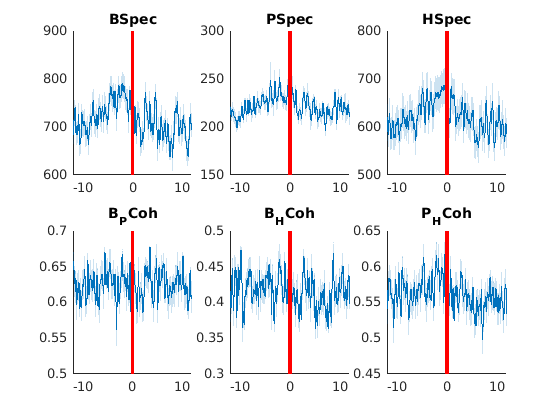

hl = 8.0449

hp = 7.0449

hl = 10.0449

hp = 9.0449

hl = 12.0449

hp = 11.0449

FreqBand=find(freqCoh>8&freqCoh<12);
for st=1:length(Structures)
    subplot(2,3,st+3)
    a=squeeze(nanmean(AllCoh.(StructurePairs{st})(:,FreqBand,:),2))';
    tpsbis=[-12+24/size(a,2):24/size(a,2):12];
    [hl,hp]=boundedline(tpsbis,nanmean(a),[stdError(a);stdError(a)]','alpha'),hold on;
    xlim([-12 12])
    title([ StructurePairs{st} 'Coh'])
    line([0 0],ylim,'color','r','linewidth',3) 
end

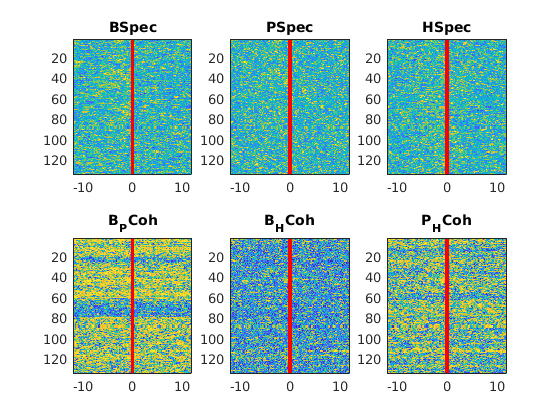

FreqBand=find(freqSpec>8&freqSpec<12);
figure
for st=1:length(Structures)
    subplot(2,3,st)
    a=squeeze(nanmean(AllSpec.(Structures{st})(:,FreqBand,:),2))';
    tpsbis=[-12+24/size(a,2):24/size(a,2):12];
    imagesc(tpsbis,1:size(a,1),zscore(a')'),hold on;
    xlim([-12 12])
    caxis([-3 3])
    title([ Structures{st} 'Spec'])
    line([0 0],ylim,'color','r','linewidth',3) 
end
FreqBand=find(freqCoh>8&freqCoh<12);
for st=1:length(Structures)
    subplot(2,3,st+3)
    a=squeeze(nanmean(AllCoh.(StructurePairs{st})(:,FreqBand,:),2))';
    tpsbis=[-12+24/size(a,2):24/size(a,2):12];
    imagesc(tpsbis,1:size(a,1),a),hold on;
    xlim([-12 12])
    title([ StructurePairs{st} 'Coh'])
    line([0 0],ylim,'color','r','linewidth',3) 
    caxis([0 1])
end